# Solution surrogate approximation 

## Target of the approximation problem

We consider the Helmholtz solution in the unit ball with wavenumber $\kappa$ such as

k=5;

We define the *maximum mode number* `L` in the approximation target:

L=5*k;

The *solution surrogate* is defined as a superposition of spherical waves $b_{\ell}^m$, namely


$$u=\sum_{\ell=0}^{\infty}\sum_{m=-\ell}^{\ell}\hat{u}_{\ell}^m\,b_{\ell}^m.$$


We need to define the modal content of the solution surrogate `u` by specifying the coefficients in the *spherical wave* basis $b_{\ell}^m$ for $0\leq |m|\leq \ell$. This is done by defining a *modal matrix* `M` whose lines are of the form $(\ell,m,\hat{u}_{\ell}^m)$, where $\ell$ is the *degree*, $m$ is the *order*, and $\hat{u}_{\ell}^m$ is the associated coefficient.

M=[];
for l=0:L
    ulm=randn(2*l+1,1)/max(1,l-k);
    M=[M;l*ones(2*l+1,1),(-l:l)',ulm];
end

The coefficients $\{\hat{u}_{\ell}^m\}_{\ell,m}$ within the expansion are products of normally-distributed random numbers (with mean 0 and standard deviation 1) and the scaling factors $[\max\{1,\ell-\kappa\}]^{-1}$. Since the coefficients of any Helmholtz solution decay in modulus as $o(\ell^{-1})$ for $\ell \rightarrow \infty$, this scenario is quite challenging.

The target of the approximation problem `u` can then be constructed as:

u=@(x)sol_surrogate(M,k,x);	

Here we plot the real part of the solution surrogate `u`. The parameters `n1` and `n2` determine the resolution of the images.

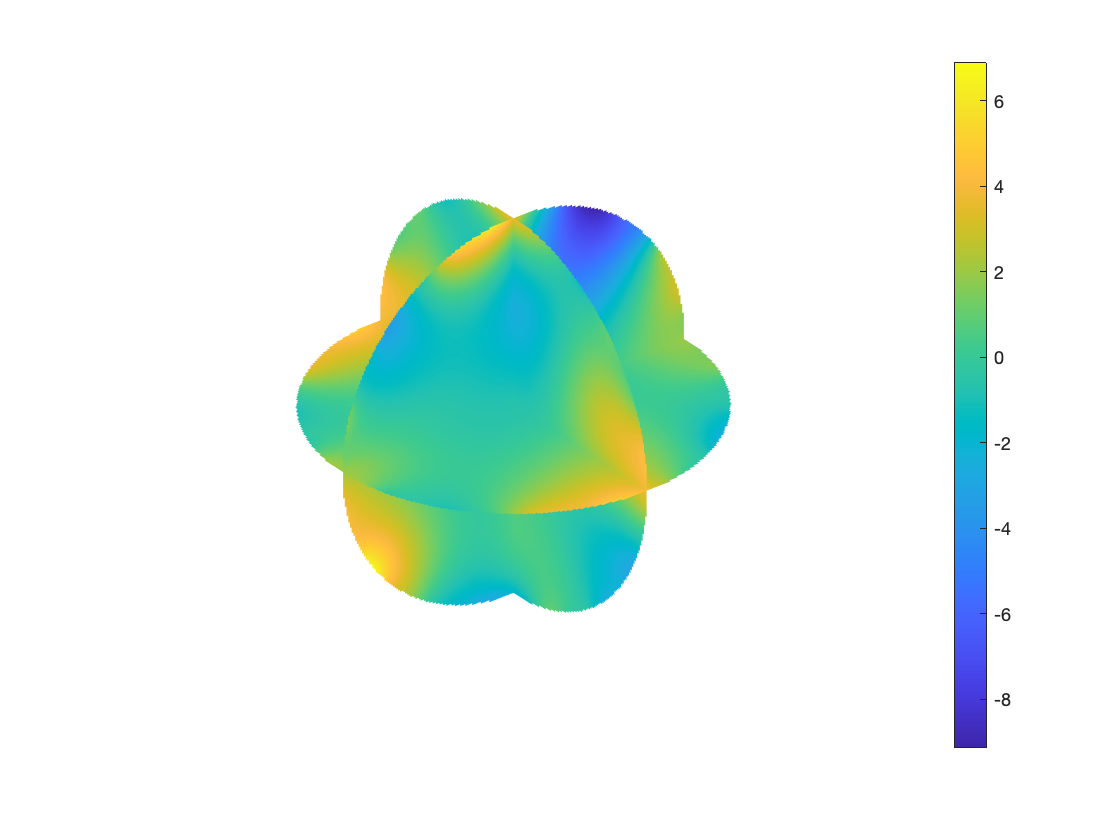

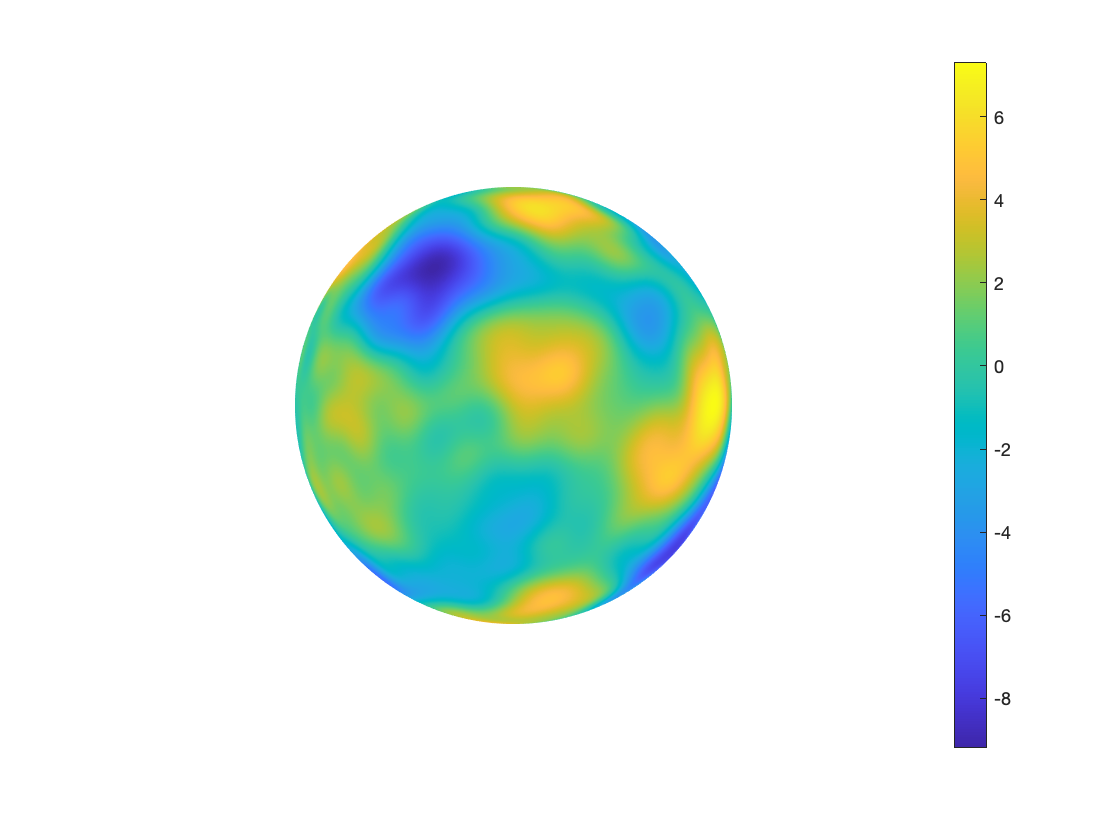

n1=200; n2=400; plot_sph(u,n1,n2);

## Reconstruction method

The approximation will be reconstructed by sampling the target on the boundary of the unit ball. To do so, we need to know the *dimension of the approximation set* `P` that we are going to use. Since we want to use *extremal systems of points* to describe the propagation directions of the plane waves, we need `P` to be a perfect square, therefore

P=4*(L+1)^2;

We can determine the number of sampling nodes necessary for a successful reconstruction, based on `P`; we chose for simplicity an oversampling ratio of 2. If we want to employ extremal points to define the sampling points on the boundary, we need their number to be a perfect square too.		 

S=ceil(sqrt(2*P));

The almost-equispaced boundary nodes and associated weights are then constructed as:

X=MD(S); WX=X(:,4); X=X(:,1:3);

The *right-hand-side* `b` of the linear system can then be readily constructed:

b=sqrt(WX).*u(X);

## Approximation by propagative plane waves

We construct the *propagative plane wave approximation set* by using extremal points:

d=MD(Ps); d=d(:,1:3)'; W=sqrt(1/P);

We define the linear system *matrix *`A` as:

A=sqrt(WX).*approx_set(k,d,W,X);

We compute the *coefficients of the approximation* `xi` through the *regularized SVD decomposition*

e=1e-14; xi=solve_RSVD(A,b,e);

and define the *solution approximation* `U` as a superposition of propagative plane waves.

U=@(x)approx_set(k,d,W,x)*xi;

We define the *absolute error function* `err`.

err=@(x)abs(U(x)-u(x)); 

We can calculate the relative residual `acc` to gauge the level of precision achieved.

acc=norm(A*xi-b)/norm(b)

acc = 0.0413

We did not achieve any accuracy at all! This is because the coefficients `xi` are too large.

stab=norm(xi)/norm(M(:,3))

stab = 1.8008e+12

Here we plot the absolute error function `err`. The parameter `Clim` adjusts the minimum colorbar values for the two displayed plots.

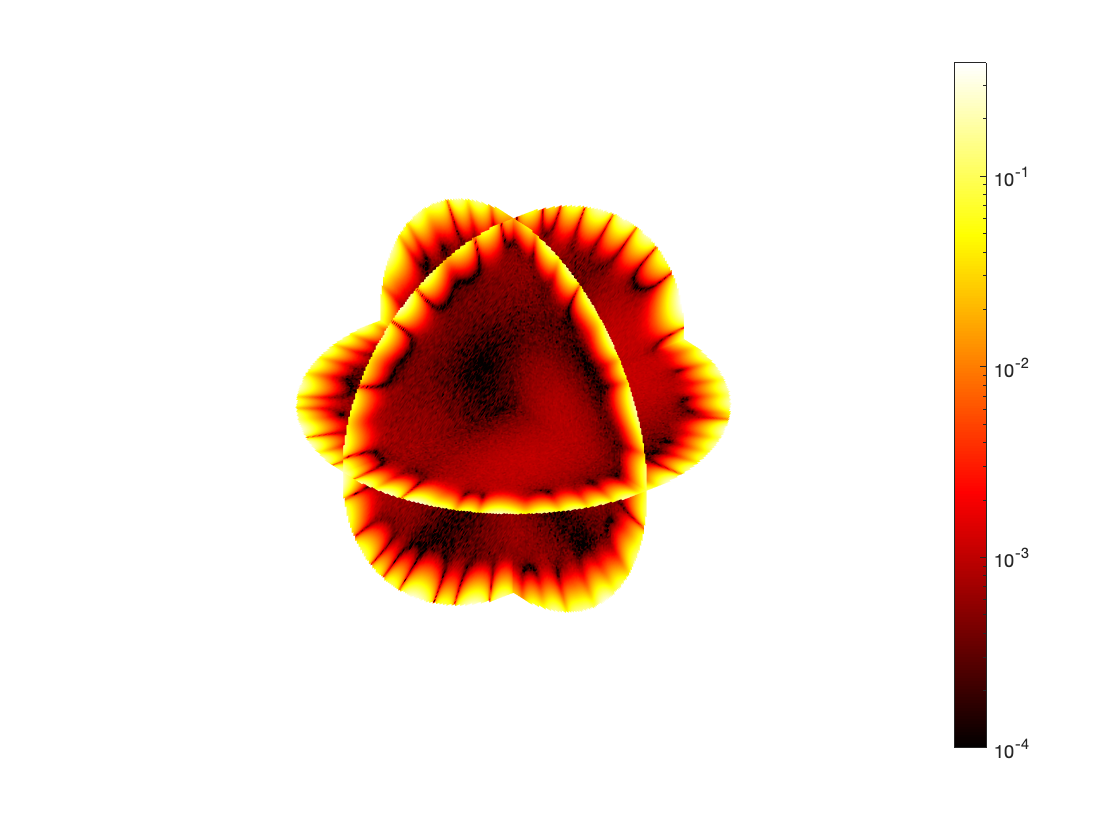

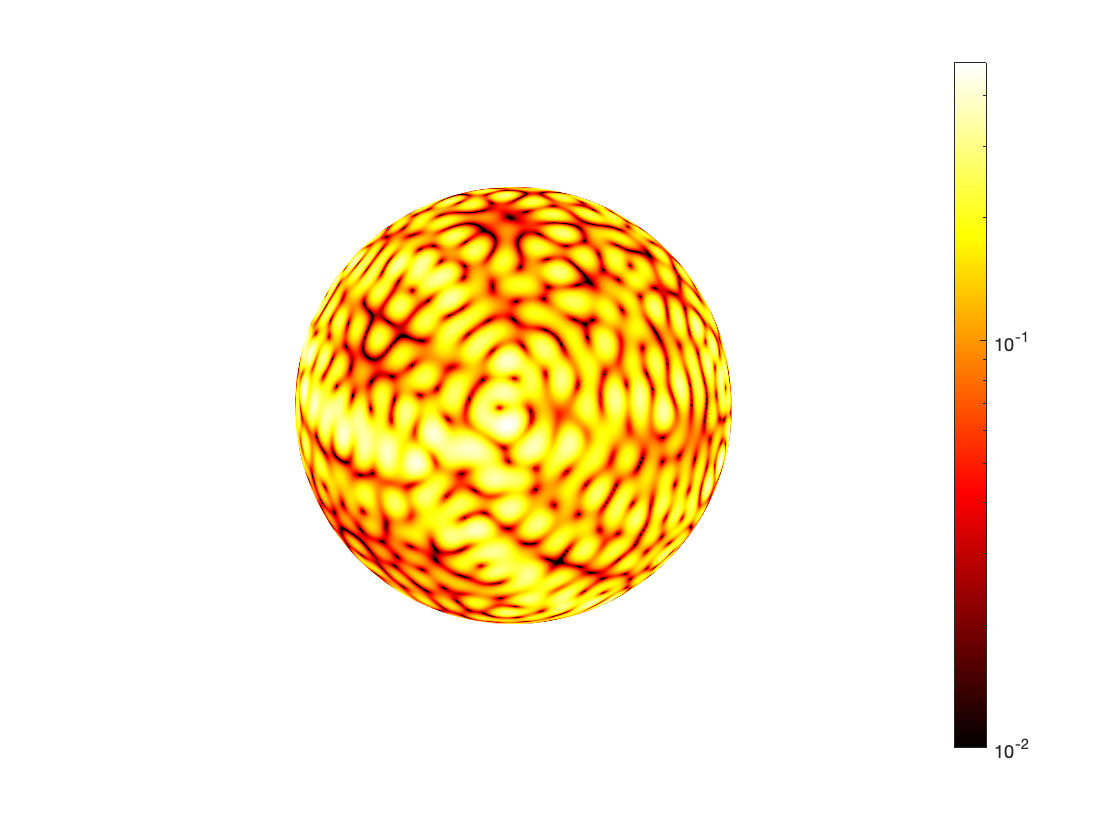

Clim=[1e-4,1e-2]; plot_sph(err,n1,n2,Clim);

## Approximation by evanescent plane waves

We construct the *evanescent plane wave approximation set* thanks to the so-called `sobol` strategy. We first sample `P` points in $[0,1]^4$.

points=net(scramble(sobolset(4),'MatousekAffineOwen'),P)';

Then we determine the *parameters* related to the evanescent plane wave set thanks to the *Inverse Transform Sampling technique*, namely

th1=acos(1-2*points(1,:)); th2=2*pi*points(2,:); th3=2*pi*points(3,:); zeta=inversion(k,L,points(4,:),1e-12);

It is possible to choose other types of sampling strategies, for instance `deterministic`, `random`, `extremal_sobol`, and `extremal_random`.

These parameters are used to construct the evanescent plane wave approximation set.

d=direction_set(k,th1,th2,th3,zeta,'sobol'); W=sqrt(1./(P*TruncKernel(k,L,zeta,'sobol')));

We now proceed as previously done. Let's define the linear system matrix `A` as:

A=sqrt(WX).*approx_set(k,d,W,X);

We compute the coefficients of the approximation `xi` through the regularized SVD decomposition

e=1e-14; xi=solve_RSVD(A,b,e);

and define the solution approximation `U` as a superposition of evanescent plane waves.

U=@(x)approx_set(k,d,W,x)*xi;

We define the absolute error function `err`.

err=@(x)abs(U(x)-u(x)); 

We compute the relative residual `acc` as a measure of the accuracy.

acc=norm(A*xi-b)/norm(b)

acc = 7.2877e-10

We roughly get 8 digits of accuracy! The size of the coefficients remains quite high:

stab=norm(xi)/norm(M(:,3))

stab = 858.6306

Here we plot the absolute error function `err`.

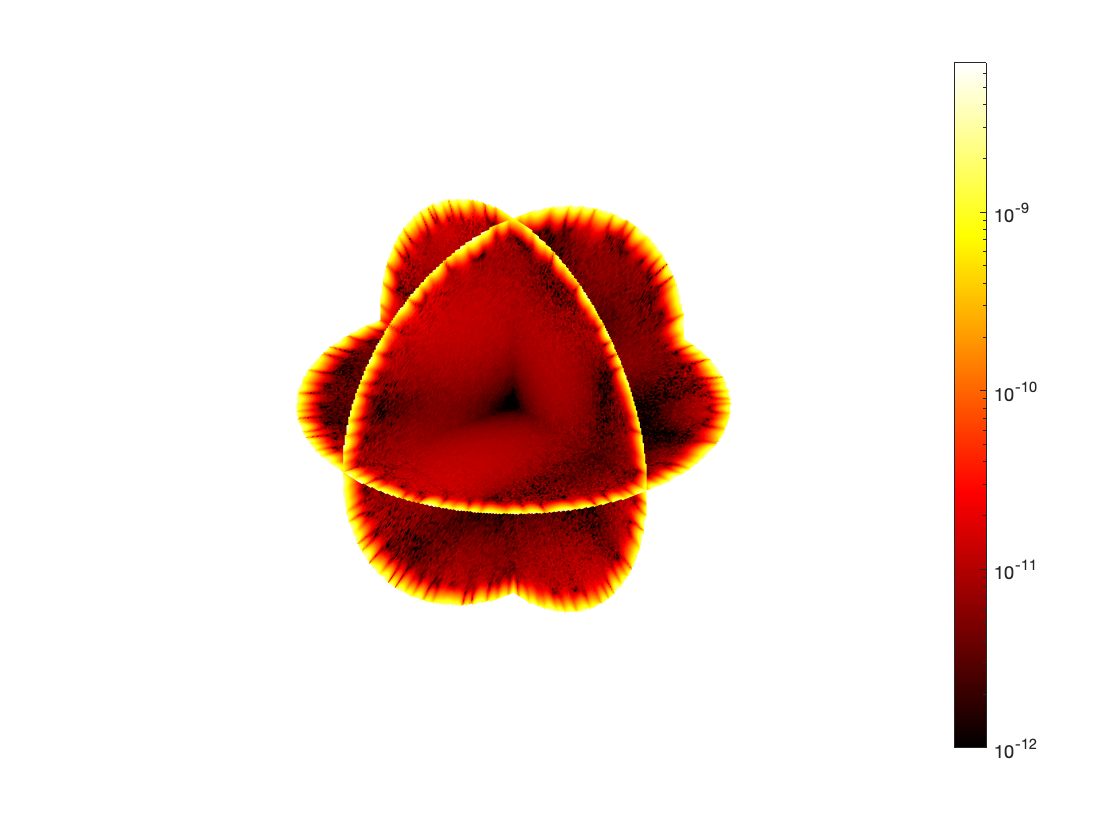

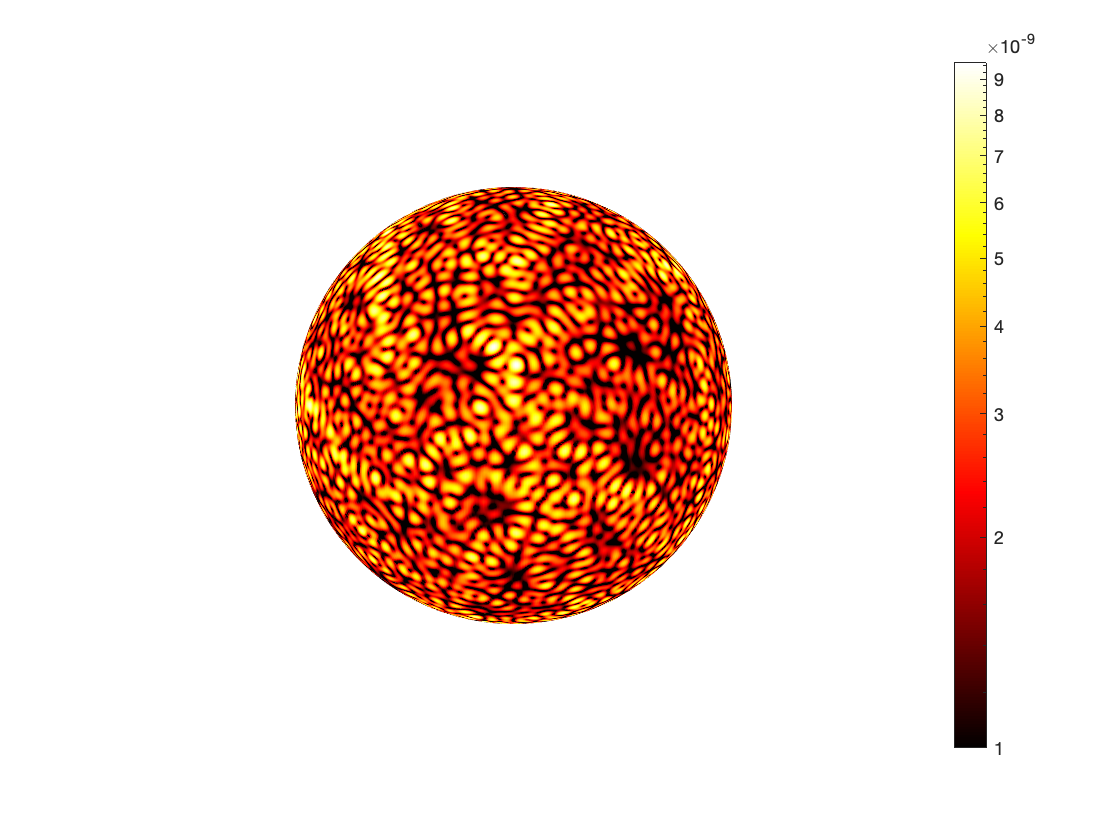

Clim=[1e-12,1e-9]; plot_sph(err,n1,n2,Clim);

## Down to machine precision

Let's raise the number of evanescent plane waves.

P=9*(L+1)^2;

The following convenience function can expedite the above approximation process significantly.

[U,err,acc,stab] = Dirichlet_sampling(k,u,L,P,e,'sobol');

It can be verified that the relative residual achieved now is extremely close to machine precision (almost 14 digits of accuracy):

acc

acc = 4.0134e-14

The size of the coefficients is also greatly reduced:

stab/norm(M(:,3))

ans = 0.3313

Here we plot again the absolute error function `err`.

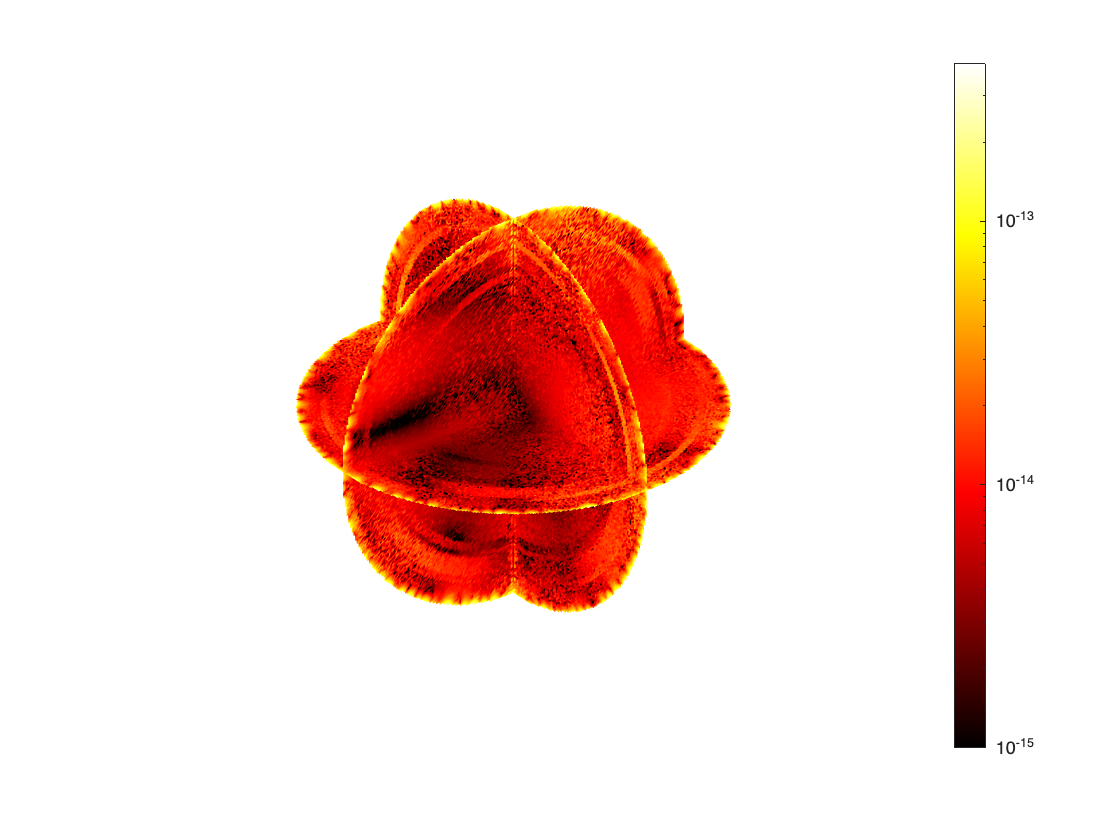

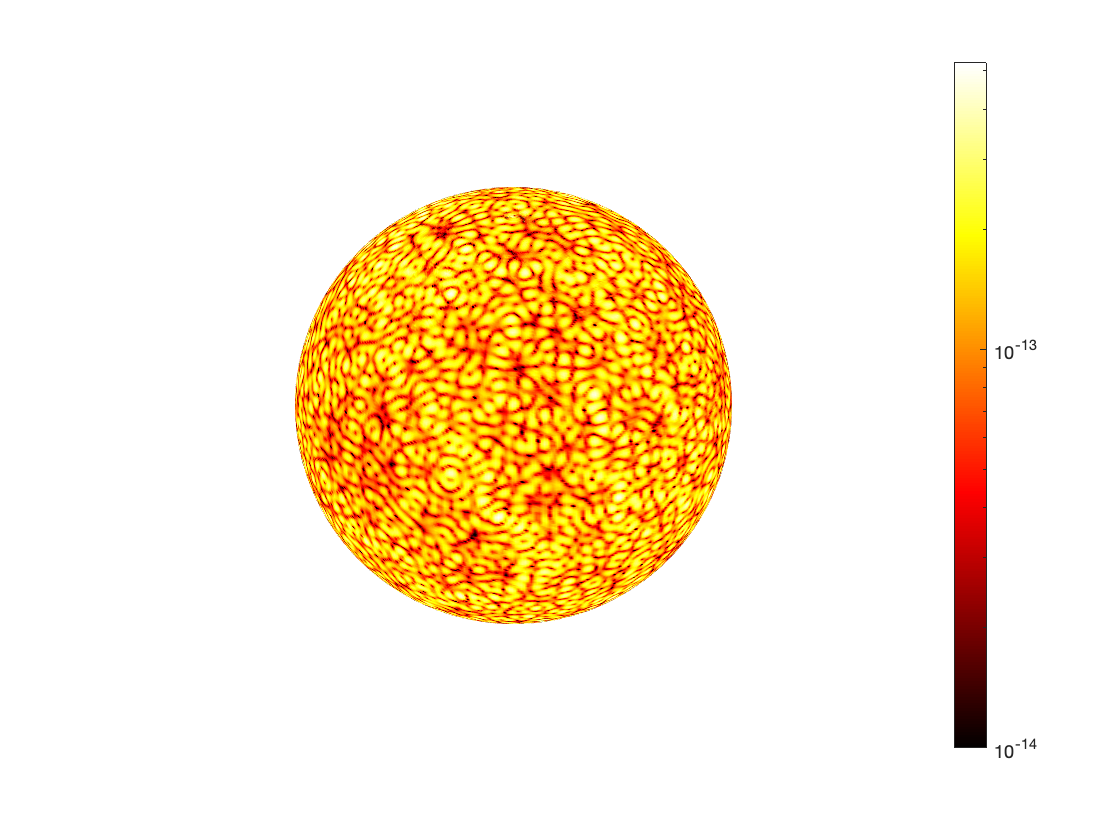

Clim=[1e-15,1e-14]; plot_sph(err,n1,n2,Clim);